a.)

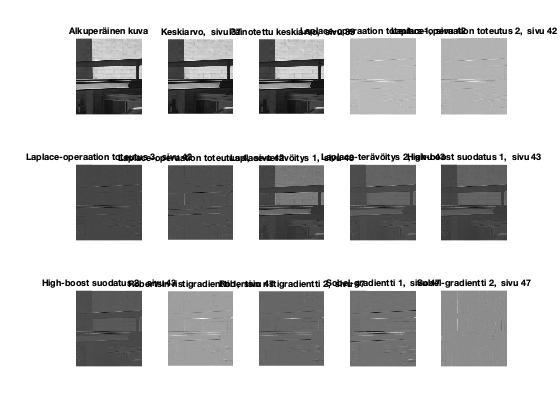

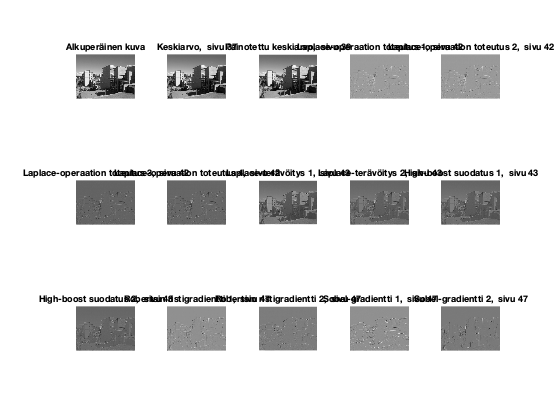

load('maskit.mat');
pictures = dir('kuvat3');


for i=1:max(size(pictures))
    k = 1;
    str = pictures(i).name;
    if (strcmp(str,'.')==0)&&(strcmp(str,'..')==0)
        figure()
        str =  ("kuvat3/" + str);
        pict = imread(str);
        for n=0:max(size(maskit))
            if n == 0
                subplot(3, (max(size(maskit))+1)/3, k)
                imshow(pict)
                title('Alkuperäinen kuva', 'FontSize', 9)
            else 
                filtpict = filter2(maskit{n,1}, pict);
                subplot(3, (max(size(maskit))+1)/3, k)
                imshow(filtpict, [])
                title(maskit{n,2}, 'FontSize', 9)
            end
            k = k + 1;
        end
    end
end

b.)

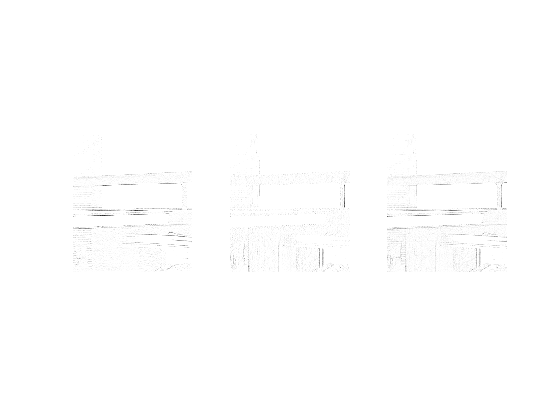

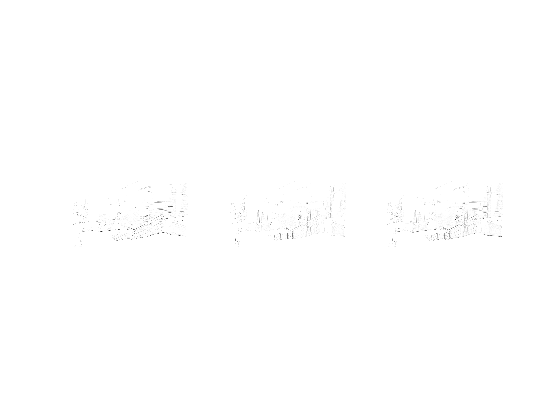

pictures = dir('kuvat3');

for i=1:max(size(pictures))
    str = pictures(i).name;
    if (strcmp(str,'.')==0)&&(strcmp(str,'..')==0)
        Gx = [];
        Gy = [];
        str =  ("kuvat3/" + str);
        pict = imread(str);
        for x=1:size(pict,1)-2
            for y=1:size(pict,2)-2
                Gx(x,y) = ((pict(x+2,y)+2*pict(x+2,y+1)+pict(x+2,y+2))-(pict(x,y)+2*pict(x,y+1)+pict(x,y+2)));
                Gy(x,y) = ((pict(x,y+2)+2*pict(x+1,y+2)+pict(x+2,y+2))-(pict(x,y)+2*pict(x+1,y)+pict(x+2,y)));
            end
        end
        figure;
        subplot(1, 3, 1);
        Gx = abs(Gx);
        Gy = abs(Gy);
        Gx = Gx/max(Gx(:));
        Gy = Gy/max(Gy(:));
        imshow(uint8(255*(1-Gx)), [])
        subplot(1, 3, 2);
        imshow(uint8(255*(1-Gy)), [])
        grad = abs(Gx)+abs(Gy);
        grad = grad/max(grad(:));
        grad = uint8(255*(1-grad));
        subplot(1, 3, 3);
        imshow(grad,[])
    end
end